## Desire the cutoff frequency with regard to alaising

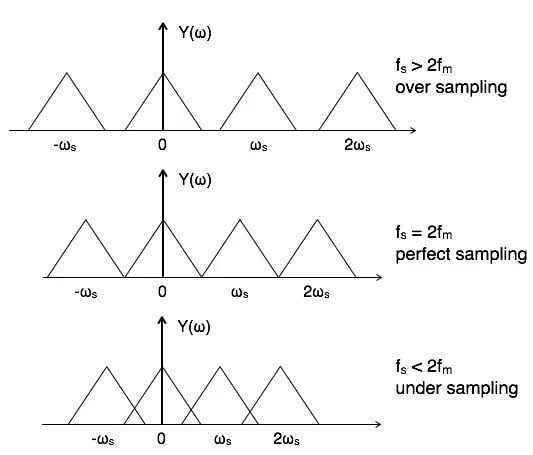

[https://technobyte.org/whats-aliasing-dsp-how-to-prevent-it/](https://technobyte.org/whats-aliasing-dsp-how-to-prevent-it/)


$$\textrm{highest}\;\textrm{signal}\;\textrm{frequency}<\frac{\textrm{sampling}\;\textrm{frequency}}{2}$$


If that is not the case, the periodic repetition of the DFT  would overlap and cause noise in the higher frequencys region. 

if cutoff_f >= fs/2
    disp(['Alaising due to cutoff frequenzy ' num2str(cutoff_f) 'Hz >= sampling frequenzy/2 ' num2str(fs/2) 'Hz'])
else
    disp(['No alaising due to cutoff frequenzy ' num2str(cutoff_f) 'Hz < sampling frequenzy/2 ' num2str(fs/2) 'Hz'])
end

No alaising due to cutoff frequenzy 5000Hz < sampling frequenzy/2 22050Hz


## Lowpass filter convolution in time domain


$$(f * g)_\ell = \sum_{k=-\infty}^{\infty} f_k g_{\ell-k}$$


#### Convolution theorem:


$$(f * g)_\ell = \sum_{k=-\infty}^{\infty} f_{\ell-k} g_k$$


#### Normalized cutoff frequency (script page 48)


$$\hat{\omega}_c = \frac{2\omega_c}{\omega_s}$$


w_c_norm = 2*cutoff_f/fs;

#### Filter coefficients of the low pass filter with cutoff frequency

#### $\omega_c$ of length $n$ (script page 48)


$$\text{si}(x) = \begin{cases}
    \frac{\sin(x)}{x} & \text{if } x \neq 0 \\
    1 & \text{if } x = 0
\end{cases}$$



$$\text{sinc}(x)={si}(\pi x)$$



$$x_k = \hat{\omega}_c \text{sinc}(\hat{\omega}_c(k - \frac{n}{2})), \quad k = 0, \ldots, n-1$$


n=100; % order
k = 0:n-1;
x_k = w_c_norm*sinc(w_c_norm*(k-(n-1)/2));

#### Hamming Window


$$w_k = 0.54 - 0.46 \cos\left(\frac{2\pi k}{n}\right), \quad k = 0, \ldots, n-1$$



$$x_k = x_k \cdot w_k$$


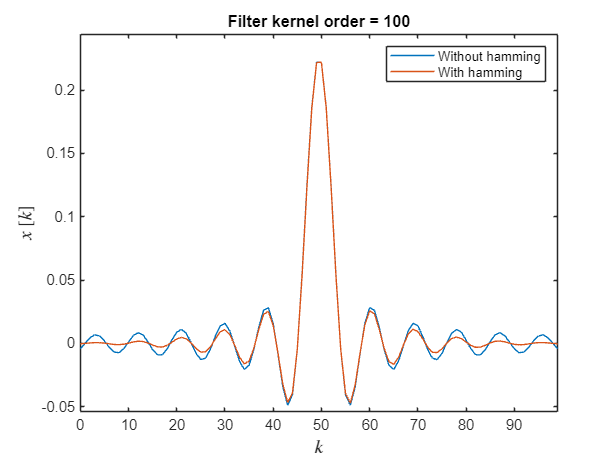

w_k = 0.54-0.46*cos(2*pi*k/n);
x_k_ham = x_k.*w_k;

figure()
plot(k,x_k)
hold on
plot(k,x_k_ham)
hold off
title(['Filter kernel order = ' num2str(n)])
xlabel('$k$','Interpreter','Latex', 'FontSize', 13);
ylabel('$x$ [$k$]','Interpreter','Latex', 'FontSize', 13);
legend('Without hamming','With hamming')
xlim([0 length(k)-1])
ylim([min(x_k)*1.1 max(x_k)*1.1])

#### Discrete convolution in time domain


$$h_\ell = \sum_{k=0}^{n-1} f_{\ell-k}x_k$$


h1 = zeros(size(signal_1)); % Initialisation of the filtered signal
h2 = zeros(size(signal_2)); % Initialisation of the filtered signal

for l = 1:N
    h1(l) = sum( signal_1(max(1, l-n+1):min(length(signal_1), l)) .* x_k_ham(max(1, n-l+1):min(n,length(signal_1)-l+n)) );
    h2(l) = sum( signal_2(max(1, l-n+1):min(length(signal_2), l)) .* x_k_ham(max(1, n-l+1):min(n,length(signal_2)-l+n)));
end

## Plot the original and the lowpassfiltered signal

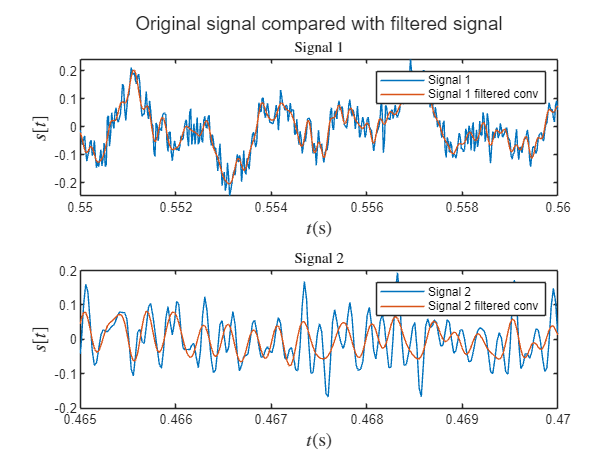

figure()
p=tiledlayout(2,1);
title(p,'Original signal compared with filtered signal','FontSize', 13)
nexttile
plot(t,signal_1)
hold on
plot(t-ts*n/2,h1)
hold off
title('Signal 1','Interpreter','Latex')
xlabel('$t$(s)','Interpreter','Latex', 'FontSize', 13)
ylabel('$s[t]$', 'Interpreter', 'latex', 'FontSize', 13);
legend('Signal 1','Signal 1 filtered conv')
xlim([0.55 0.56])%xlim([0 max(t)])

nexttile
plot(t,signal_2)
hold on
plot(t-ts*n/2,h2)
hold off
title('Signal 2','Interpreter','Latex')
xlabel('$t$(s)','Interpreter','Latex', 'FontSize', 13)
ylabel('$s[t]$', 'Interpreter', 'latex', 'FontSize', 13);
legend('Signal 2','Signal 2 filtered conv')
xlim([0.465 0.47])%xlim([0 max(t)])

## Comparison with the Matlab FIR1 filter 

(Check if our filtering works properly)

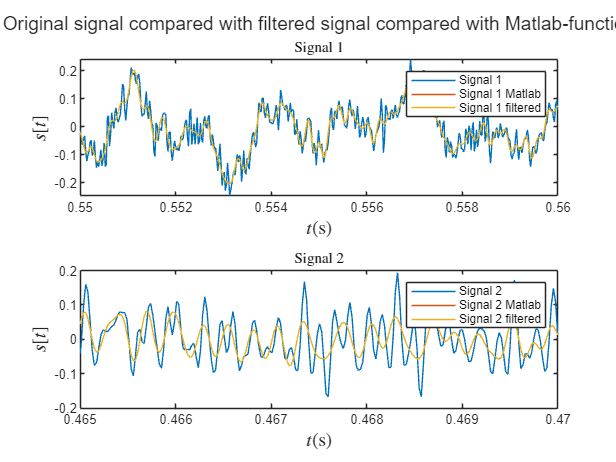

w_hamming_FIR1_pre=hamming(n,'symmetric'); 
h_LP_hamming_FIR1_pre = fir1(n-1,cutoff_f/(fs/2),'low',w_hamming_FIR1_pre); 
signal_1_hamming_FIR1_pre=conv(signal_1,h_LP_hamming_FIR1_pre,'same');
signal_2_hamming_FIR1_pre=conv(signal_2,h_LP_hamming_FIR1_pre,'same');

figure()
p=tiledlayout(2,1);
title(p,'Original signal compared with filtered signal compared with Matlab-function','FontSize', 13)
nexttile
plot(t,signal_1)
hold on
plot(t,signal_1_hamming_FIR1_pre)
plot(t-ts*n/2,h1)
hold off
title('Signal 1','Interpreter','Latex')
xlabel('$t$(s)','Interpreter','Latex', 'FontSize', 13)
ylabel('$s[t]$', 'Interpreter', 'latex', 'FontSize', 13);
legend('Signal 1','Signal 1 Matlab','Signal 1 filtered')
xlim([0.55 0.56])%xlim([0 max(t)])

nexttile
plot(t,signal_2)
hold on
plot(t,signal_2_hamming_FIR1_pre)
plot(t-ts*n/2,h2)
hold off
title('Signal 2','Interpreter','Latex')
xlabel('$t$(s)','Interpreter','Latex', 'FontSize', 13)
ylabel('$s[t]$', 'Interpreter', 'latex', 'FontSize', 13);
legend('Signal 2','Signal 2 Matlab','Signal 2 filtered')
xlim([0.465 0.47])%xlim([0 max(t)])